% Experiment 3 (HOG + SVM): Bounding Box Image Area as Input: CUB_200_2011 dataset.
% Author: Sujan Khanal
% ID: u3258630

close all;
clear variables;
clc;

%Check if we have a GPU available and clear any old data from it
if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      



## Read the training, validation and test partitions from the relevant


folder = "C:\Users\u3258630\Desktop\CVIA\u3258630_CVIA_Asgn1_Final\CUB_200_2011\";
trainingImageNames = readtable(fullfile(folder, "train200.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate200.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test200.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Read bounding box information from bounding_boxes.txt. The format is

boundingBoxes = readtable(folder + "bounding_boxes.txt", ...
    'ReadVariableNames', false);
boundingBoxes.Properties.VariableNames = {'index', 'x', 'y', 'w', 'h'};

% Map bounding box information to the respective image file name
train_image_box_map = returnMapping(trainingImageNames, boundingBoxes);
val_image_box_map = returnMapping(validationImageNames, boundingBoxes);
test_image_box_map = returnMapping(testImageNames, boundingBoxes);

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

This is where the image cropping based on the bounding box information happens through the readImagesIntoDatastoreBB_Fast function and related helper functions.

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, train_image_box_map);
disp('Training set class samples:');

Training set class samples:


countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, val_image_box_map);
disp('Validation set class samples:');

Validation set class samples:


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames',   'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, test_image_box_map);

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', 'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, train_image_box_map);

validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', 'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, val_image_box_map);


disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  


disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  


disp('Test set class samples:');

Test set class samples:


countEachLabel(testImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
labelsValidation = arrayDatastore(validationImageDS.Labels);
labelsTest = arrayDatastore(testImageDS.Labels);

cdsTraining = combine(trainingImageDS, labelsTraining);
cdsValidation = combine(validationImageDS, labelsValidation);
cdsTest = combine(testImageDS, labelsTest);

% Resize all images to a common width and height
targetSize = [100, 100];
cdsTraining = transform(cdsTraining, @(x) preprocessData(x,targetSize));
cdsValidation = transform(cdsValidation, @(x) preprocessData(x,targetSize));
cdsTest = transform(cdsTest, @(x) preprocessData(x,targetSize));

## Display a sample image from the datastore and HOG features

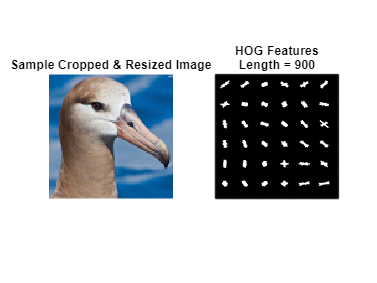

figure(1);
img = cdsTraining.read{1};
imgGray = rgb2gray(img);
[hogFeature, visualization] = extractHOGFeatures(imgGray, 'CellSize', [16 16]);
subplot(1, 2, 1);
imshow(img);
title('Sample Cropped & Resized Image');
subplot(1, 2, 2);
plot(visualization);
title({'HOG Features'; ['Length = ' num2str(length(hogFeature))]});

## Extract HOG features

%% Extract HOG features from all images

cellSize = [16 16];
hogFeatureSize = length(hogFeature);

% Extract HOG features for training set
numTrainImages = numel(cdsTraining.UnderlyingDatastores{1, 1}.UnderlyingDatastores{1, 1}.Files);
trainingFeatures = zeros(numTrainImages, hogFeatureSize, 'single');
reset(cdsTraining);
for i = 1:numTrainImages
    imgFromDS = read(cdsTraining);
    imgGray = rgb2gray(imgFromDS{1});
    trainingFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

% Extract HOG features for test set
numTestImages = numel(cdsTest.UnderlyingDatastores{1, 1}.UnderlyingDatastores{1, 1}.Files);
testFeatures = zeros(numTestImages, hogFeatureSize, 'single');
reset(cdsTest);
for i = 1:numTestImages
    imgFromDS = read(cdsTest);
    imgGray = rgb2gray(imgFromDS{1});
    testFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

%% Apply z-score normalization

trainingFeatures = zscore(trainingFeatures);
testFeatures = zscore(testFeatures);


## **Move Feature Data to GPU**

%% Move data to GPU
disp('Moving feature data to GPU...');

Moving feature data to GPU...


XtrainGPU = gpuArray(trainingFeatures);
XtestGPU = gpuArray(testFeatures);
Ytrain = trainingImageDS.Labels; % Labels remain on CPU
disp('Data moved to GPU.');

Data moved to GPU.


## Train a multi-class SVM on GPU

%% Train SVM on GPU Using Best Hyperparameters
disp('Training SVM classifier on GPU with best hyperparameters...');

Training SVM classifier on GPU with best hyperparameters...



t = templateSVM(...
    'KernelFunction', 'gaussian', ...         % RBF = Gaussian
    'BoxConstraint', 998.46, ...
    'KernelScale', 'auto', ...
    'Standardize', true, ...
    'Solver', 'SMO', ...
    'Verbose', 1);

SVMClassifier = fitcecoc(XtrainGPU, Ytrain, ...
    'Learners', t, ...
    'Coding', 'onevsall');  % Standard One-vs-All strategy for multi-class

|===================================================================================================================================|
|   Iteration  | Set  |   Set Size   |  Feasibility  |     Delta     |      KKT      |  Number of   |   Objective   |   Constraint  |
|              |      |              |      Gap      |    Gradient   |   Violation   |  Supp. Vec.  |               |   Violation   |
|===================================================================================================================================|
|            0 |active|         7057 |  9.999999e-01 |  2.000000e+00 |  1.000000e+00 |            0 |  0.000000e+00 |  0.000000e+00 |
|         1000 |active|         7057 |  7.440462e-01 |  7.144213e-03 |  3.651381e-03 |          621 | -1.526542e+02 | -2.798624e-06 |
|         1497 |active|         7057 |  2.340905e-01 |  7.711649e-04 |  4.037619e-04 |          627 | -1.526560e+02 | -1.481094e-06 |

 Exiting Active Set upon convergence due to DeltaGradient.
|=


disp('SVM training complete.');

SVM training complete.


## Test the accuracy on the test partition

%% Predict on Test Set and Gather Results
disp('Predicting labels on GPU...');

Predicting labels on GPU...


YPredGPU = predict(SVMClassifier, XtestGPU);
YPred = gather(YPredGPU);  % Move predictions back to CPU
YTest = testImageDS.Labels; % Labels already on CPU

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.1623

disp(['Final Test Accuracy (using best parameters): ', num2str(accuracy*100), '%']);

Final Test Accuracy (using best parameters): 16.2288%


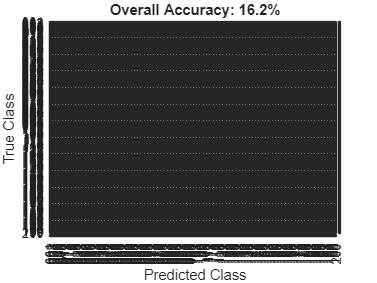



% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%");

## Compute classwise positive recogniton rate

classwisePosRecog = zeros(height(order), 1);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog(iI) = round(100 * m(iI, iI) / samplesPerRow(iI), 1);
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog)

   33.3000
         0
    9.1000
         0
   22.2000
   12.5000
    8.3000
   44.4000
         0
   16.7000
         0
   18.2000
   33.3000
   16.7000
         0
         0
    9.1000
   22.2000
    8.3000
         0
    8.3000
   27.3000
    8.3000
   20.0000
    8.3000
   16.7000
         0
   58.3000
    8.3000
         0
   16.7000
   20.0000
    8.3000
   16.7000
    8.3000
   41.7000
    8.3000
   16.7000
   16.7000
    8.3000
   50.0000
   16.7000
         0
   25.0000
   16.7000
   41.7000
    8.3000
   50.0000
         0
   41.7000
   50.0000
   75.0000
   66.7000
    8.3000
   25.0000
         0
   25.0000
   18.2000
    8.3000
   16.7000
   33.3000
         0
   41.7000
         0
         0
         0
   41.7000
   41.7000
   25.0000
   41.7000
    8.3000
         0
    8.3000
    8.3000
   36.4000
    8.3000
    8.3000
         0
   50.0000
   33.3000
   41.7000
         0
   75.0000
   16.7000
   25.0000
   50.0000
    8.3000
   58.3000
   66.7000
   50.0000
         0

## Helper function for resizing images in transform

function data_out = preprocessData(data, targetSize)
try
    data_out{1} = imresize(data{1}, targetSize(1:2)); % Resize images
    data_out{2} = data{2};  % Keep labels as they are
catch e
    % This is solely for debugging
    disp(e)
end
end

## Helper function mapping image names to bounding boxes and vice versa

function image_box_map = returnMapping(ImageNames, boundingBoxes)
image_box_map = containers.Map;
for i = 1:size(ImageNames, 1)
    fn = ImageNames{i,2}{1};
    fn = split(fn, "\");
    fn = split(fn, "/");
    image_box_map(fn{end}) = [boundingBoxes{ImageNames{i,1}, 2:5}];
end
end

